# Linear Mixed Model demo

This demonstration was prepared by Bogdan Petre and Tor Wager. Updated: May 2023

The demo includes code to perform a mixed-effects analysis on a dataset in both Matlab and R. The published version runs the Matlab code.

To reproduce the analysis, you must have the dataset, which is in the  `CANlab_help_examples` repository on Github, on your Matlab path. it is in the subfolder `canlab_mixed_effects_matlab_demo1`

## About the dataset

The example uses a subset of data from an ongoing study, provided for model demonstration purposes only. Do not reuse or reshare this dataset for other purposes. It was collected by Tor Wager's Cognitive and Affective Neuroscience lab at the University of Colorado.

behav_dat = readtable('study_behav_dat_sid_14_164.csv');

behav_dat(1:5, :)

% we remove this subject who only has placebo but no contorl data
% glmfit_multilevel isn't designed to handle this
%behav_dat(behav_dat.sid == 113,:) = [];

***Variables***

**Yint** - pain intensity rating

**Yunp** - pain unpleasantness rating.

**RTint** - reaction time for intensity ratings

**RTunp** - reaction time for unpleasantness ratings

**stimLvl** - low, medium or high. 46.5C, 47C and 47.5C, possibly different

  for earliest subjects, but we think all with different temps are excluded

**sid** - subject id label. Corresponds to PGsXXX labels used internally by

  the lab. Subject is the most typical grouping variable for specifying random effects.

**heat** - 1 if heat trial, 0 for pressure trials

**placebo** - 0.5 for stimulation of placebo treated sight, -0.5

  otherwise

**run** - run number(1,2,3 or 4). Runs 1 and 4 are ctrl. 2 and 3 are

  placebo.

**trial** - trial number within run. Centered.

**vif** - variance inflation factor for use with fMRI data. can ignore this.

***Preparation***

These data were prepared with several preprocessing steps:

-  Response times <= 0.02s were removed (we had sticky button problems and based on temporal distribution of responses it seems that anything < 0.02 is likely to be due to this rather than a deliberate response)

-  Response times >= 5.01 seconds were removed. These are timeouts without a click and it's ambiguous whether the cursor location recorded corresponds to the subjects' rating or not.

- Subjects with sid 1-13 were removed due to changes to the paradigm at this stage of the study. Subject 6 retained because this subject was processed out of order and actually was run on the newer paradigm.

- Subject 23 and 84 are removed because too few of their responses passed the timing criteria above

## Mixed effects: Motivation and specifying mixed effects models in Matlab

We usually want to make inferences about population-level effects: For example, whether pain ratings increase as stimulus intensity increases on average in a population.  In a model, these effects are termed **fixed effects** because we assume there is a fixed population-level value (e.g., for the slope of the relationship) that we are trying to estimate based on data.  We do so by generalizing over variables that are randomly sampled from a population, most typically the individual subjects studied. These are random variables, and statistical models that caputure variation across them treat them as **random effects**.  

In a typical study in the psychological and brain sciences (and beyond), we measure one data point per person, and assume that the variation across them is independent, i.e., that each person is a random draw from a population. The standard linear regression model (what we call the **single-level model** here) reflects this assumption. It models observed measurements (denoted ***y***) one or more predictors (denoted ***x1***, ***x2***, etc.) as fixed effects, and assumes that the variation across people is measurement error that is independent across people conditional on the fixed effects -- that is, one person's observed measurement cannot be predicted from another person's, except insofar as they have similar values on predictor variables. 

We can think of each person as a different **level** of a random varlable.  The effect of subject is therefore termed a random effect.   Whereas stimulus intensity and other fixed effects often have (a) a discrete number of levels or (b) are continuously distributed along a fixed dimension, subject variables have levels *randomly* drawn from a larger population.  Critically, the variation across subjects is estimated in the model's error term; the more variation across subjects, the less statistically significant the result, and the lower our confidence that there is a real effect. Therefore, the standard single-level model treats subject as a random effect, as long as there is only one measurement per person.

When we have multiple observations from the same person, collected at different times and/or in different task conditions that we'd like to compare, it becomes important to keep track of the **sources of variation** and account for them properly in our statistical model. In this case, we care about the differences between task conditions **within-person** as well as potential sources of variation **between-person**. This is a very typical case in psychological and brain sciences. In this tutorial, for example, we care about the effects of stimulus temperature (**x1**) and placebo (**x2**) within-person, and whether these effects are significantly different from zero at the population level.  

Designing studies with within-subjects comparisons is often highly desirable.  Within-person effects can usually be tested in a much more powerful way, because each person serves as their own control in comparisons, eliminating many sources of noise. For example, people may report higher or lower pain scores for a variety of reasons unrelated to your experimental manipulation of temperature. Comparing two groups, one receiving a 47-degree stimulus and another receiving a 48-degree stimulus, would compare the effect of temperature to all the other sources of variation that could cause one person to report more pain than another. Testing each participant on both temperatures and comparing them eliminates these sources and is something like an order of magnitude more powerful.  

If we collect multiple observations per person and use a typical single-level statistical model, the assumption of independent errors will be violated, because we are collecting multiple measures from the same person. If people differ systematically from one another in the ***y*** values being measured (which is nearly always the case), the errors will be correlated. The correlation structure will not be captured by the statistical model, and the P-values and degrees of freedom will be too liberal (wrong), resulting in an increase in false positives. Subject is a **grouping variable** (**g**) that must be accounted for in the statistical model.

The simplest valid way to deal with this problem is to calculate difference scores, or **contrast** values, that capture within-person effects and reduce the dataset to a series of one difference score per person. For example, I may calculate for each person a linear effect of temperature on pain (x1_i) or a placebo vs. control contrast score.  Then,  I can use the standard single-level, independent-errors model to estimate the strength of the population-level fixed effect compared to the variation across subjects (i.e., the variation across levels of the subject  The error term in the model reflects variation across subjects, as it should.  We can think of this as a two-stage model: The **first level** uses a standard linear model to estimate effects (temperature, placebo) for each person, and the coefficients from this model are passed to a **second-level** linear model to estimate whether the population-level coefficients are non-zero on average across persons.  CANlab's **glmfit_multisubject** uses this two-stage approach, without any "bells and whistles" if desired, but also with an interative update that approximates a full mixed-effects model in a computationally efficient way.

In a **mixed effects** model, these two stages are combined. The dataset includes multiple observations from the same person, and effects can be specified as either **fixed** or **random**.  The fixed effects are the experimental or observational predictors that we want to make inferences about, and they can vary either within-person or between-person. The random effects are the levels of random variables that we'd like our fixed effects to generalize over. 

Matlab and R both use Wilkinson-Rogers notation, which allows the user to enter a text string that specifies which effects are treated as fixed and which as random.  For example, 


$$y=1+\;\left(1\;|\;g\right)$$


estimates an intercept (population mean) across levels fo the random grouping variable g. The model includes a parameter to estimate the mean for each level of *g*.  If *g *is subject and there at 10 subjects, it will estimate 10 means. 

The following model includes an intercept and two predictors (e.g., temperature and placebo), and random effects for all three parameters. There is a random intercept and random slopes for both predictors. i.e., a person's temperature effect is estimated as the slope of a regression line across temperatures, and a person's  placebo effect is estimated as the slope of the line varying condition from placebo to control. Statistical significance for each parameter is based on the population-average estimate for each slope compared with the inter-subject variation in slopes. 


$$y=1+\mathrm{x1}+\mathrm{x2}+\left(1+\mathrm{x1}+\mathrm{x2}\;|\;g\right)$$


Matlab has a very handy guide to Wilkinson-Rogers notation for simple mixed-effects models:

[https://www.mathworks.com/help/stats/wilkinson-notation.html](https://www.mathworks.com/help/stats/wilkinson-notation.html)

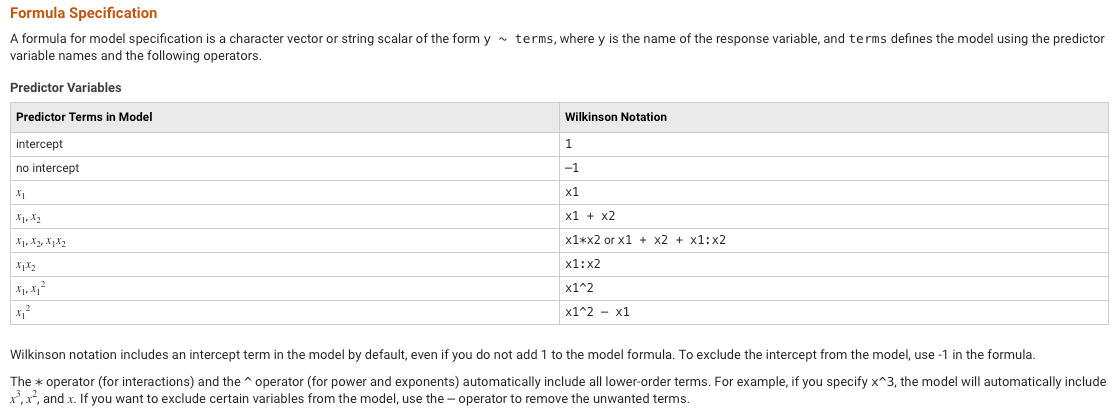

The formulas are similar in R software, particularly lme4. Here are some examples:

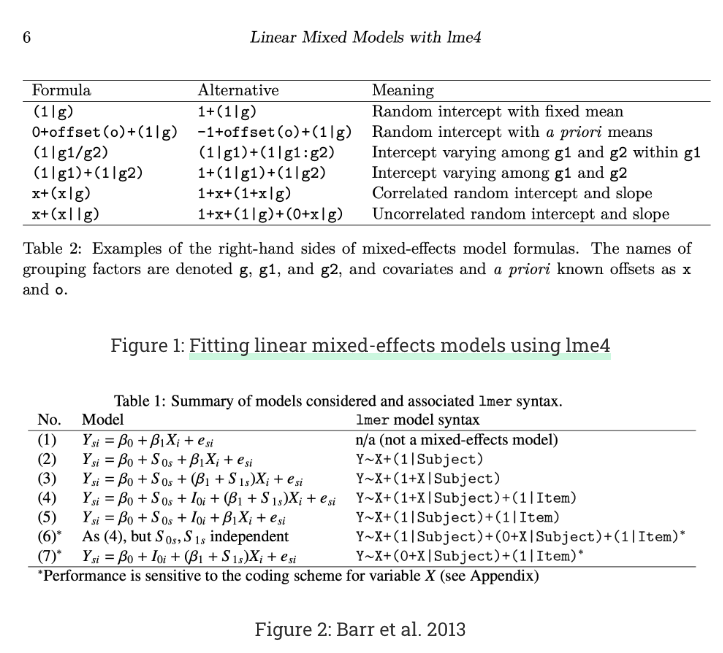

- Barr, Dale J, R. Levy, C. Scheepers und H. J. Tily (2013). *Random effects structure for confirmatory hypothesis testing: Keep it maximal*. Journal of Memory and Language, 68:255– 278.

### Nested and crossed random effects

nested:

(1|School/Class) or equivalently (1|School) + (1|Class:School)

Crossed effects are not nested, so independent

`(1|School) + (1|Class)`

[https://stats.stackexchange.com/questions/228800/crossed-vs-nested-random-effects-how-do-they-differ-and-how-are-they-specified](https://stats.stackexchange.com/questions/228800/crossed-vs-nested-random-effects-how-do-they-differ-and-how-are-they-specified)

[https://xiaoyingpu.github.io/note/cheat/](https://xiaoyingpu.github.io/note/cheat/)

[https://yury-zablotski.netlify.app/post/mixed-effects-models-2/](https://yury-zablotski.netlify.app/post/mixed-effects-models-2/)

Nature methods summary:

[https://www.nature.com/articles/nmeth.3137.epdf?shared_access_token=D0d0MK8Gti6Hwao6TU76XtRgN0jAjWel9jnR3ZoTv0N0DeGI7mpe9VDCZJYcOB1gQiRNP5rNycymLbaP0G2LjuiXfuonXncuZhUt5-rVjhIKYJQMwoZ8w1NupHzwmAND](https://www.nature.com/articles/nmeth.3137.epdf?shared_access_token=D0d0MK8Gti6Hwao6TU76XtRgN0jAjWel9jnR3ZoTv0N0DeGI7mpe9VDCZJYcOB1gQiRNP5rNycymLbaP0G2LjuiXfuonXncuZhUt5-rVjhIKYJQMwoZ8w1NupHzwmAND)

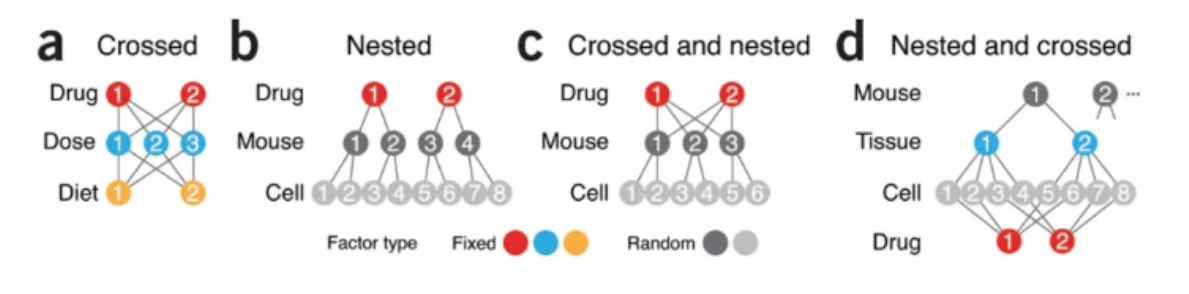

x+(1+x|ID|g)

### **Degrees of freedom and statistical inference ** 

One makes inferences about the fixed effects (population mean).  Importantly, not all programs provide P-values and inferential statistics or adjust the degrees of freedom (an estimate of how many independent sources of error you're averaging over; the more the better). In Matlab mixed-effects models, we use the commonly used Satterthwaite method for estimating them (see below), which requires an extra step after model fitting. The estimated degrees of freedom is nearly always higher than the number of subjects, but lower than the total number of observations. It should usually be much lower, and closer to the number of subjects, but sometimes this can be much higher. **glmfit_multisubject **uses a lower-bound degrees of freedom estimate, which makes it generally more conservative. 

## Using fitlme to create a LinearMixedModel object in Matlab

The fitlme code below does the following:

% - test placebo effect on heat trials
% - Control for stimulus level and test for interaction effects.
% - Model random subject (sid) intercepts and slopes.
% - Intercept is modeled implicitly both at the group and subject level.
% That is, you do not need to enter 'Yint ~ 1 + stimLvl*placebo ...'
% in the model in order for it to include an intercept term, because fitlme
% adds it automatically.
% - Use REML estimator instead of the default ML.


heat_dat = behav_dat(behav_dat.heat == 1,:); % Use heat trials only

m = fitlme(heat_dat, 'Yint ~ stimLvl*placebo + (stimLvl*placebo | sid)',...
    'FitMethod','REML');

Other notes:

% - Adding stimLvl*placebo automatically adds stimLvl, placebo, and
% stimLvl*placebo effects. You do not need to enter
% 'Yint ~ 1 + stimLvl + placebo + stimLvl*placebo ...'
% 'Yint ~ stimLvl*placebo ...' does the same thing.
%
% - Adding (stimLvl*placebo | sid) adds random effects for the intercept
% (1), added automatically if another random effect is added), stimLvl,
% placebo, and stimLvl*placebo effects.

***Sample output*** Here is a sample of the output.

% - The P-values for Fixed effects coefficients do not generalize across
% levels of the random factors. The df and P-values use the overall number
% of observations (1704) minus the number of fixed-effect parameters (4 =
% 1 (intercept) + 1 (stimLvl) + 1 (placebo) + 1 (stimLvl*placebo).
% This is not correct for an inference across levels of the random effect
% of subject (sid).
% Thus, we need to use the anova() function below to get the correct
% inferences.

% Fixed effects coefficients (95% CIs):
%     Name                        Estimate     SE           tStat      DF      pValue        Lower        Upper
%     '(Intercept)'                 0.16402     0.011235     14.598    1700    1.4571e-45      0.14198      0.18606
%     'stimLvl'                    0.073984    0.0091767     8.0622    1700    1.3994e-15     0.055985     0.091983
%     'placebo'                -0.054471    0.0086796    -6.2757    1700    4.4069e-10    -0.071495    -0.037447
%     'stimLvl:placebo'        0.0065812     0.014501    0.45385    1700       0.64999     -0.02186     0.035022
%
% Random effects covariance parameters (95% CIs):
% Group: sid (121 Levels)
%     Name1                       Name2                       Type          Estimate      Lower        Upper
%     '(Intercept)'               '(Intercept)'               'std'            0.11924      0.10469     0.13581
%     'stimLvl'                   '(Intercept)'               'corr'            0.7489      0.71099     0.78247

inspect model coefficients (ignore p-values)

m.Coefficients

get satterthwaite corrected p-values LinearMixedModel.anova Perform hypothesis tests on fixed effect terms. STATS = anova(LME) tests the significance of each fixed effect term in the linear mixed effects model LME and returns a table array STATS. If DummyVarCoding is used in fitlme call, anova will perform Type III hypothesis tests across DummyVar (not shown here).

anova(m,'dfmethod','satterthwaite')

Satterthwaite corrected p-values can also be obtained using LinearMixedModel/coefTest, which can be useful for certain circumstances where anova doesn't return the specific contrast of interest by default. One circumstance where this arises is when you have DummyVarCoding in your fitlme invocation, but it's also useful for performing post-hoc comparisons.

The following implementation tests stimLvl = 0, which should provide the same results as above, while the other should post-hoc test whether placebo + stimLvl = 0, which conceptually amounts to testing if placebo effects are larger than a 1C **decrease** in stimulus intensity. The test is somewhat contrived, but mostly selected to illustrate how to use coefTest. 

[Pa, Fa, DF1a, DF2a] = coefTest(m,[0,1,0,0],0,'dfmethod','satterthwaite');

[Pb, Fb, DF1b, DF2b] = coefTest(m,[0,1,1,0],0,'dfmethod','satterthwaite');

t = array2table([Pa,Fa,DF1a,DF2a; Pb, Fb, DF1b, DF2b],'VariableNames',...
    {'pValue','F','DF1','DF2'},'RowNames',{'stimLvl','placebo = (-1)*stimLvl'})

***Satterthwaite correction***

% Using the satterthwaite option for df estimates the error degrees of
% freedom based on the rank
% The formula was developed by the statistician Franklin E. Satterthwaite and a derivation of the
% result is given in Satterthwaite's article in Psychometrika (vol. 6, no. 5, October 1941).
% This site is useful for deriving the df in the two-sample case: https://secure-media.collegeboard.org/apc/ap05_stats_allwood_fin4prod.pdf
% Code for Satterthwaite df calculation for mulitple regression can be found in
% fit_gls.m (Martin Lindquist), and is included here for the
% no-autocorrelation (AR(p), p==0) case:

% A = W;   % for ar p = 0 case; weights
% R = (eye(T) - X * invxvx * X' * iV);        % Residual inducing matrix
%
% Wd = R * A * inv(iV) * A';                  % inv(iV) = Covariance matrix
% df = (trace(Wd).^2)./trace(Wd*Wd);       % Satterthwaite approximation for degrees of freedom

***Model properties*** You can query the model object (m) to get its properties. e.g.,

help LinearMixedModel
m.Rsquared
m.VariableInfo                          % all variables in input dataset and which are in model
m.Variables(1:5, :)                     % all variables in input dataset
X = designMatrix(m); X(1:5, :)          % Fixed-effects design matrix
Xg = designMatrix(m, 'Random'); whos('Xg')          % Random-effects design matrix


% This option,  'DummyVarCoding', 'effects', effects-codes, which we
% prefer:
m = fitlme(heat_dat,'Yint ~ stimLvl*placebo + (stimLvl*placebo | sid)',...
    'FitMethod','REML', 'DummyVarCoding', 'effects');
% help anova says:
%     To obtain tests for the Type III hypotheses, set the 'DummyVarCoding'
%     to 'effects' when fitting the model.

## Simple two-level mixed effects using CANlab glmfit_multilevel

Mixed-effects models differ in their assumptions and implementation details. glmfit_multilevel is a fast and simple option for running a two-level mixed effects model with participant as a random effect. It implements a random-intercept, random-slope model across 2nd-level units (e.g., participants). it fits regressions for individual 2nd-level units (e.g., participants), and then (optionally) uses a precision-weighted least squares approach to model group effects. It thus treats participants as a random effect. This is appropriate when 2nd-level units are participants and 1st-level units are observations (e.g., trials) within participants. glmfit_multilevel was designed with this use case in mind.

glmfit_multilevel requires enough 1st-level units to fit a separate model for each 2nd-level unit (participant). If this is not the case, other models (igls.m, LMER, etc.) are preferred.

Degrees of freedom: glmfit_multilevel is conservative in the sense that the degrees of freedom in the group statistical test is always based on the number of subjects - 2nd-level parameters. The df is never higher than the sample size, which you would have with mixed effects models that estimate the df from the data. This causes problems in many other packages, particularly when there are many 1st-level observations and they are uncorrelated, resulting in large and undesirable estimated df. 

% update appropriately
addpath(genpath(['/home/' getenv('USER') '/.matlab/canlab/CanlabCore']));

% provides glmfit_multilevel() dependency RB_empirical_bayes_params()
addpath(genpath(['/home/' getenv('USER') '/.matlab/canlab/MediationToolbox']));

Prepare the dataset** glmfit_multilevel takes cell array input, with one cell per subject Y contains the response for each subject, and X the within-subject design matrix.

First, we need to turn the dataset into cell arrays:

u = unique(heat_dat.sid);
[Y, X] = deal(cell(1, length(u)));

Y_name = 'Yint';
X_var_names = {'stimLvl' 'placebo'};

Y_var = heat_dat.(Y_name);

X_var = zeros(size(Y_var, 1), length(X_var_names));

for j = 1:length(X_var_names)
    X_var(:, j) = heat_dat.(X_var_names{j});
end

for i = 1:length(u)
    
    wh = heat_dat.sid == u(i);  % indicator for this subject
    
    Y{i} = Y_var(wh);
    
    for j = 1:length(X_var_names)
        
        X{i}(:, j) = X_var(wh, j);
        
    end
    
end

% X2 is the 2nd-level (between-person) design matrix.
% we don't have any between-person predictors, so X2 is empty here:
X2 = [];

X2_names = {'2nd-level Intercept (average within-person effects)'};

***Between-person predictors*** Note: if we had a between-person predictor, the intercept would be first, and names would be, e.g., X2_names = {'2nd-level Intercept (overall group effect)' '2nd-lev predictor: Group membership'}

***Within-person variation*** glmfit_multilevel takes a summary statistics approach with precision-reweighting. it fits a model for each person individually. Therefore, each individual must have variance in Y and individual X.

**Run the model**

stats = glmfit_multilevel(Y, X, X2, 'names', X_var_names, 'beta_names', X2_names);

% The 'weighted' option uses Empirical Bayes weighting for a single-step
% precision reweighting. This is a simple version of what is acccomplished
% by fitlme in Matlab or LMER in R, or igls.m (Lindquist/Wager).

stats = glmfit_multilevel(Y, X, X2, 'names', X_var_names, 'beta_names', X2_names, 'weighted');

% The 'boot' option, with 'bootsamples', n, runs n boostrap samples at the 2nd level:
% Run with 1000 bootstrap samples initially, and more are added based on P-value tolerance to avoid instability with too-few samples

stats = glmfit_multilevel(Y, X, X2, 'names', X_var_names, 'beta_names', X2_names, 'weighted', 'boot');

## Plotting data and effects

This is a crucial part of the analysis process!

with glmfit_multilevel, the 'plots' option generates some plots. you can also use functions including barplot_columns() to plot summary 2nd-level stats, and lineplot_multisubject() to plot individual and group within-person effects

% % stats = glmfit_multilevel(Y, X, X2, 'names', X_var_names, 'beta_names', X2_names, 'weighted', 'boot', 'plots');

effectcolors = {[.5 .5 .5] [.7 .4 .4] [.4 .4 .7]};

Plot the individual within-person effect scores and group summary statistics Note: P values and Cohen's d from the barplot_columns output may not match your model results in stats exactly, because it provides a simple t-test on each column. so you should prefer the stats from the mixed model output.

create_figure('2nd level stats'); 
barplot_columns(stats.first_level.beta', 'names', stats.inputOptions.names, 'colors', effectcolors, 'nofigure');
ylabel(Y_name);
title('Naive individual within-person scores');
drawnow, snapnow

If you are using subject scores on within-person effects for other purposes, e.g., to regress on brain variables, then using the Empirical Bayes estimates for these is a good idea!! They are likely to be more accurate representation of the individual participants' scores than the naive within-person effects.

create_figure('2nd level stats comparison', 1, 2); 
subplot(1, 2, 1);
barplot_columns(stats.first_level.beta', 'names', stats.inputOptions.names, 'colors', effectcolors, 'nofigure');
ylabel(Y_name);
title('Naive individual within-person scores');

subplot(1, 2, 2);
barplot_columns(stats.Y_star, 'names', stats.inputOptions.names, 'colors', effectcolors, 'nofigure');
ylabel(Y_name);
title('Empirical Bayes individual scores');
drawnow, snapnow

With line_plot_multisubject, you can plot the within-person scores for one effect at a time. This does not control for other effects, and stats reported are simple summary stats, so you should prefer the stats from the mixed model output.

Get one column of X (Alternatively, you could reconstruct individual scores for marginal estimates for each level, or modify glmfit_multilevel to return this output!)

X_placebo = X;
for i = 1:length(X), X_placebo{i} = X_placebo{i}(:, 2); end

%

Create a plot, with each subject in a different color along a spectrum

create_figure('1st level effect'); 
line_plot_multisubject(X_placebo, Y);
set(gca, 'XTick', [-.5 .5], 'XLim', [-.6 .6], 'XTickLabel', {'Control' 'placebo'});

Create a plot with individuals that show positive effects in one color and negative effects in another color (Negative effects mean analgesia here)

indiv_scores = stats.Y_star(:, 3);
% or: indiv_scores = stats.first_level.beta(3, :)';

wh = indiv_scores > 0; % individuals with positive effects

poscolors = {[1 .4 .4]}; % custom_colors([.3 .3 .7], [.3 .5 1], sum(wh))';    % colors for those with pos effects
negcolors = {[.3 .3 1]}; % custom_colors([.7 .2 .2], [.7 .4 .4], sum(~wh))';    % colors for everyone else

colors = {};
colors(wh) = poscolors;
colors(~wh) = negcolors;

create_figure('1st level effect'); 
line_plot_multisubject(X_placebo, Y, 'colors', colors);
set(gca, 'XTick', [-.5 .5], 'XLim', [-.6 .6], 'XTickLabel', {'Control' 'placebo'});

## Assessing and considering correlations between the individual effects

Individuals with high stimulus responses might also show large analgesia effects

Or, commonly, the individuals with higher baseline outcomes (here, pain) might show larger effects. This is likely if there are individual differences in the ***scale*** of the outcome, such that some individuals have compressed values on the outcome relative to others, causing a proportional compression of the treatment effects. This is very common with outcome measures including self-reported symptoms and reaction times. If so, it's ambiguous what the best individual difference scores for treatment effects ought to be. They could be the effect scores in raw units, or after adjusting for potential response scale differences. 

In both these cases, the within-person effects will be correlated -- across treatment effects, in the former case, and with the intercept (average outcome value) in the latter. We can assess these empirically, using the EB estimates from our mixed-effects model:

plot_correlation_matrix(stats.Y_star, 'names', stats.inputOptions.names);
drawnow, snapnow

it's also a good idea to look at the scatterplots and marginal distributions (e.g., check for outliers)

figure; plotmatrix(stats.Y_star);
drawnow, snapnow

Here, we see that the intercept (average pain) is strongly correlated with the effect of stimLvl (intensity sensitivity) and also correlated with the effect of placebo (negatively, which is sensible as a negative effect means a larger analgesic effect). This suggests that there are individual differences in scale usage (compressed vs. expanded range) that influence the treatment effect scores when analyzed in raw units. Specifically, e.g., here about half the variation in stimulus intensity effects can be explained by overall pain report differences (r = 0.71)

This can add noise variability that masks effects (makes them non-significant) in the linear model, or when correlating with external variables (e.g., fMRI activity, another task). Or it can create artifactual positive correlations with other tasks (e.g., a different drug/treatment effect) if participants display the same scale compression/expansion across tasks. That is, we might observe positive correlations between placebo effects in pain and in a different task (allergy test) that could be caused by consistency in scale usage rather than consistency in the underlying treatment effects.

Some options for dealing with this include: 1. Include baseline scale (e.g., average outcome) as a 2nd-level covariate in the mixed-effects model. This makes the GLM a bi-linear model: Treatment effects vary linearly as a function of baseline pain.

2. Transform outcome values to be on the same scale (e.g., within-subject Z-scores or normalization of the outcome by the L2 norm)

3. Residualizing effects by removing the average outcome (individual intercepts) from each treatment effect

Here is what happens when we use Option 3. This removes the predicted effects of baseline pain from the treatment effect estimates.

We'll use the Empirical Bayes estimates because these are probably the best estimates of individual scores we have. 

Note: the resid() function has a flag that preserves the overall mean response so we can remove the covariate without removing the average treatment effects.

avg_pain = stats.Y_star(:, 1);

% Get new placebo scores
resid_placebo = resid(avg_pain, stats.Y_star(:, 3), true);

resid_stimLvl = resid(avg_pain, stats.Y_star(:, 2), true);

figure; plotmatrix([avg_pain resid_stimLvl resid_placebo]);

plot_correlation_matrix([avg_pain resid_stimLvl resid_placebo], 'names', stats.inputOptions.names);
drawnow, snapnow

## 2nd-level predictors

Mixed models can include between-person (e.g., group) predictors as well. These could include sex/gender, counterbalancing order variables, and others.

You can include between-person and within-person predictors in any mixed effects model. They can interact with (i.e., moderate) the within-person effects, and/or they can have main effects on the response.

In glmfit_multilevel, these are entered in a second-level design matrix, X2. X2 will automatically include an intercept as the first effect. One block of output stats is included for the average within-person effects (the group intercept), with one block for each of the 2nd-level predictors.

e.g., here, we will include baseline pain as a 2nd-level predictor. The first stats block reports the within-person effects at the average baseline pain, and the second reports baseline pain effects on each within-person effect (the intercept is not of interest here) 

Note: you must mean-center all 2nd-level predictors (except the intercept) for the interpretations above to hold. If you do not, your estimates of within-person effects will change and be potentially uninterpretable. Centering will be done automatically UNLESS you explicitly turn it off using the 'nocenter' option.

X2 = cellfun(@nanmean, Y)';

stats = glmfit_multilevel(Y, X, X2, 'names', X_var_names, 'beta_names', {'Average_pain'}, 'weighted', 'boot');